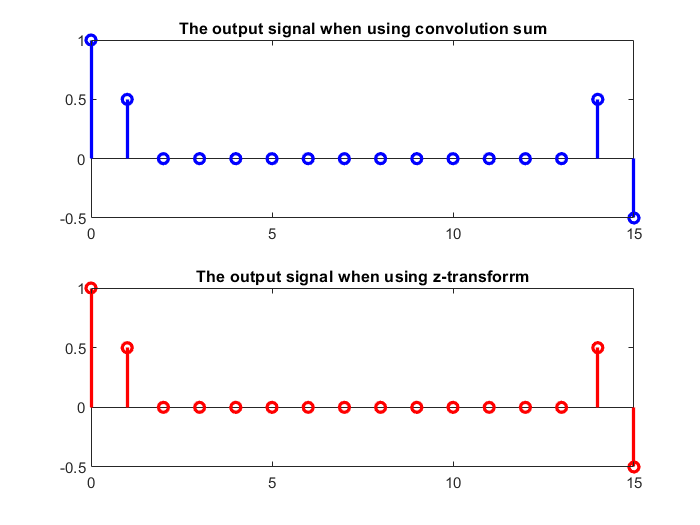

syms n z
h = [1,1,1];
n1 = 0:13;
x = cos((2*pi*n1)/3);
y1 = conv(x,h);

h2 = kroneckerDelta(n) + kroneckerDelta(n-1) + kroneckerDelta(n-2);
x2 = cos((2*pi*n)/3);
X2 = symsum(x2*(z^-n),n, 0, 13);
H2 = ztrans(h2);
y2 = iztrans(X2*H2);
n2 = 0:15;
y2 = subs(y2,n,n2);

figure
subplot(2,1,1)
stem([0:15],y1,'LineWidth',2,'Color','b')
title("The output signal when using convolution sum")
subplot(2,1,2)
stem([0:15],y2,'LineWidth',2,'Color','r')
title("The output signal when using z-transforrm")